# GFDM System Simulation

clear; clc; clf;

## Debug mode

DEBUG = false;

Set the simulation parameters.

conste_size = 4;        % Size of signal constellation (QPSK)
bps = log2(conste_size);% Bits per symbol
Es = 1;                 % Symbol energy
EbNo = (0:2:20);        % Eb/No

N_block = 1e1;          % Number of blocks
N_trial = 1e1;          % Number of Monte Carlo trials

GFDM parameters.

gfdm = struct;
gfdm.K = 512;                  % Subcarriers
gfdm.M = 3;                  % Subsymbols
gfdm.Kset = 0:511;             % Used subcarrier index

gfdm.pulse = 'dirichlet';    % Pulse shape
gfdm.Ncp = 0;                % CP length

gfdm.Kon = numel(gfdm.Kset); % Number of used subcarriers
gfdm.Mon = gfdm.M;           % Number of used used subsymbols
gfdm.D = gfdm.Kon*gfdm.Mon;  % Block size

Initialize the results vector.

berEst = zeros(size(EbNo));

Initialize prototype filters.

gfdm.g = dirichlet(gfdm.M, gfdm.K);
gfdm.A = g2A(gfdm.g, gfdm.K, gfdm.M);

if DEBUG
    % Plot A matrix
    X = 1:gfdm.D;
    figure;
    surf(X, X, abs(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('abs(A)');
    figure;
    surf(X, X, real(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('real(A)');
    figure;
    surf(X, X, imag(gfdm.A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('imag(A)');
end

GFDM simulation.

i = 1;  % Iteration

% Allocate space for transmit signals
sGFDM = zeros(N_trial*N_block * gfdm.D, 1);

for n = EbNo
    % Convert Eb/No to SNR
    snrdB = n + 10*log10(bps);

    % Reset the error and bit counters
    numErrs = 0;
    numBits = 0;
    
    while numBits < N_trial*N_block
        % ---------- Tx ----------
        % Generate binary data and convert it to symbols
        tx_data = randi([0, 1], bps, gfdm.D)';
        tx_data_symbol = bi2de(tx_data);
        
        % QPSK mapping
        qpsk_mod_data = pskmod(tx_data_symbol, conste_size, pi/conste_size, 'gray');   % QPSK modulation with Gray coding
        % Normalize symbol energy
        qpsk_mod_data_norm = (Es^0.5) * norm(qpsk_mod_data(1)) * (qpsk_mod_data);
        
        % Debug. Plot the QPSK data:
        if DEBUG && n == 0
            scatterplot(qpsk_mod_data_norm), grid;
            title('Constellation');
        end
        
        % GFDM modulation
        gfdm_data = gfdm.A * qpsk_mod_data_norm;
        
        % Cyclic prefix
        cp = gfdm_data(end-gfdm.Ncp+1: end);
        cp_data = [cp; gfdm_data];
        
        % Parallel to serial
        txSig = cp_data';
        
        % Store the transmit data
        sGFDM(numBits+(1:gfdm.D+gfdm.Ncp)) = txSig;
        
        % ----- Add AWGN noise -----
        rxSig = awgn(txSig, snrdB, 'measured');
        
        % ---------- Rx ----------
        %Serial to parallel
        rx_parallel = rxSig';
        
        % Remove cyclic prefix
        rx_rm_cp_data = rx_parallel(gfdm.Ncp+1: end);
        
        % GFDM demodulation
        rx_demod_data = gfdm.A \ rx_rm_cp_data;
        
        % QPSK demodulation
        rx_data_symbol = pskdemod(rx_demod_data, conste_size, pi/conste_size, 'gray');
        
        % Convert received symbols to bits
        rx_data = de2bi(rx_data_symbol, bps);
        
        % Calculate the number of bit errors
        nErrors = biterr(tx_data, rx_data);
        
        % Increment the error and bit counters
        numErrs = numErrs + nErrors;
        numBits = numBits + gfdm.D*bps;
    end
    
    % Estimate the BER
    berEst(i) = numErrs/numBits;
    
    % Next iteration
    i = i+1;
end

Plot PSD.

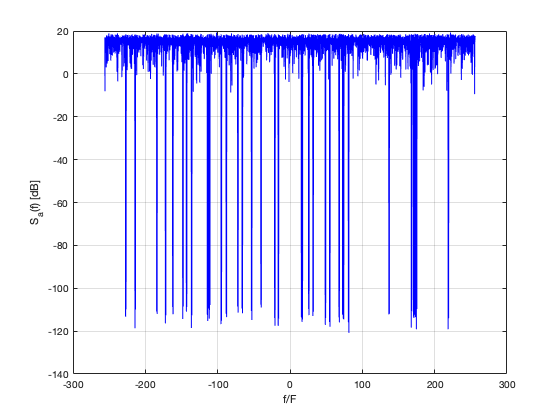

figure;
f = linspace(-gfdm.K/2, gfdm.K/2, 2*length(sGFDM)+1); f = f(1:end-1)';

plot(f, mag2db(fftshift(abs(fft(sGFDM, 2*length(sGFDM)))))/2, 'b');
% hold on;
% plot(f, mag2db(fftshift(abs(fft(whole_gfdm_data, 2*length(whole_gfdm_data)))))/2, 'r');
% hold off;
% ylim([-70, 10]);
xlabel('f/F'); ylabel('S_a(f) [dB]');
grid()

% legend({'OFDM', 'GFDM'});

Determine the theoretical BER curve by using the `berawgn` function.

berTheory = berawgn(EbNo', 'psk', conste_size, 'nondiff');

Plot the estimated and theoretical BER data.

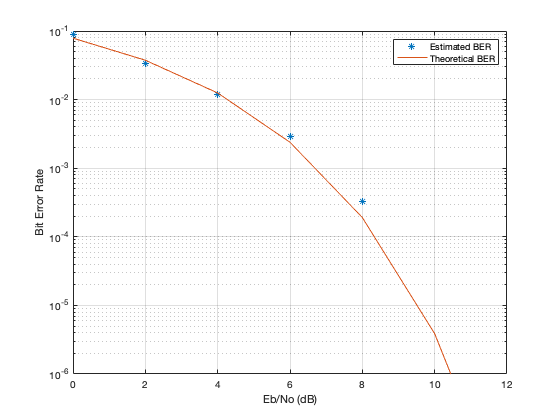

figure;
semilogy(EbNo, berEst, '*');
hold on;
semilogy(EbNo, berTheory);
grid;
legend('Estimated BER', 'Theoretical BER');
ylabel('Bit Error Rate');
ylim([10^(-6), 10^(-1)]);
xlabel('Eb/No (dB)');